theta_B = 5;
theta_K = 50;
L_1 = 0.15;
L_2 = 0.1;
G_1 = 0.08;
G_2 = 0.06;

% syms theta_B theta_K
% syms L_1 L_2 G_1 G_2
% syms psi_1 psi_2
theta_1 = pi/3;
theta_2 = pi/6;
psi_1 = theta_1 - theta_B

psi_1 = -3.9528

psi_2 = pi-theta_K-theta_2+psi_1

psi_2 = -51.3348

% psi_1 = pi/4;
% psi_2 = pi/6;

r_O = [0; 0];
r_O_A = G_1*[cos(psi_1); sin(psi_1);]

r_O_A =    -0.0551
    0.0580


r_O_B = L_1*[cos(psi_1); sin(psi_1);]

r_O_B =    -0.1033
    0.1088


r_O_C = [L_1*cos(psi_1)+G_2*cos(psi_2); L_1*sin(psi_1)+G_2*sin(psi_2);]

r_O_C =    -0.0745
    0.0562


r_O_D = [L_1*cos(psi_1)+L_2*cos(psi_2); L_1*sin(psi_1)+L_2*sin(psi_2);]

r_O_D =    -0.0552
    0.0211



figure
cla, hold on
link_1 = [r_O r_O_B]

link_1 =          0   -0.1033
         0    0.1088


plot(link_1(1,:),link_1(2,:))
link_2 = [r_O_B r_O_D]

link_2 =    -0.1033   -0.0552
    0.1088    0.0211


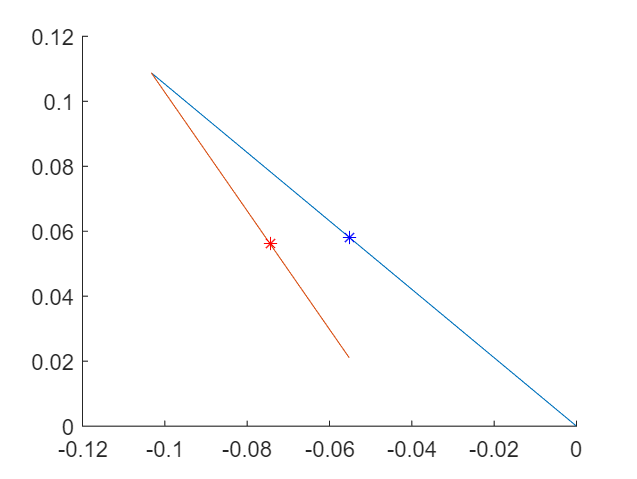

plot(link_2(1,:),link_2(2,:))

plot(r_O_A(1,:),r_O_A(2,:),'b*')
plot(r_O_C(1,:),r_O_C(2,:),'r*')